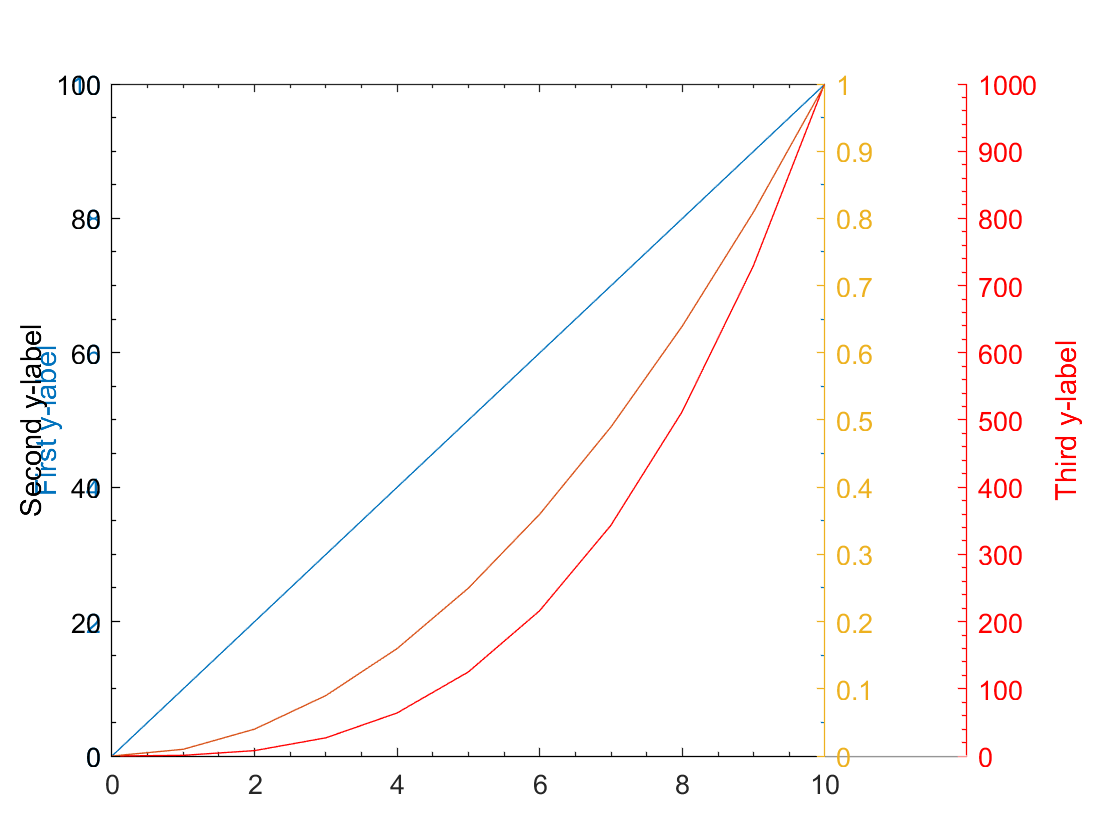

Otacky = [2000;2500;3000;4000;4500;5000;5250;5500];
Moment = [105;104;103.5;102;98;89;84;79];


%Otacky = [1421;1595;1770;1418;1545];
%Moment = [912.357;919.360;882.405;852.923;828.587];
%PlniciTlak = [248;264;270;256;264];

Vykon = (2*pi/60).*Otacky.*Moment;
Vykon2 = (2*pi/60*1.2).*Otacky.*Moment;
hold on
yyaxis left
plot(Otacky, Vykon)
yyaxis right
plot(Otacky, Moment)
hold off

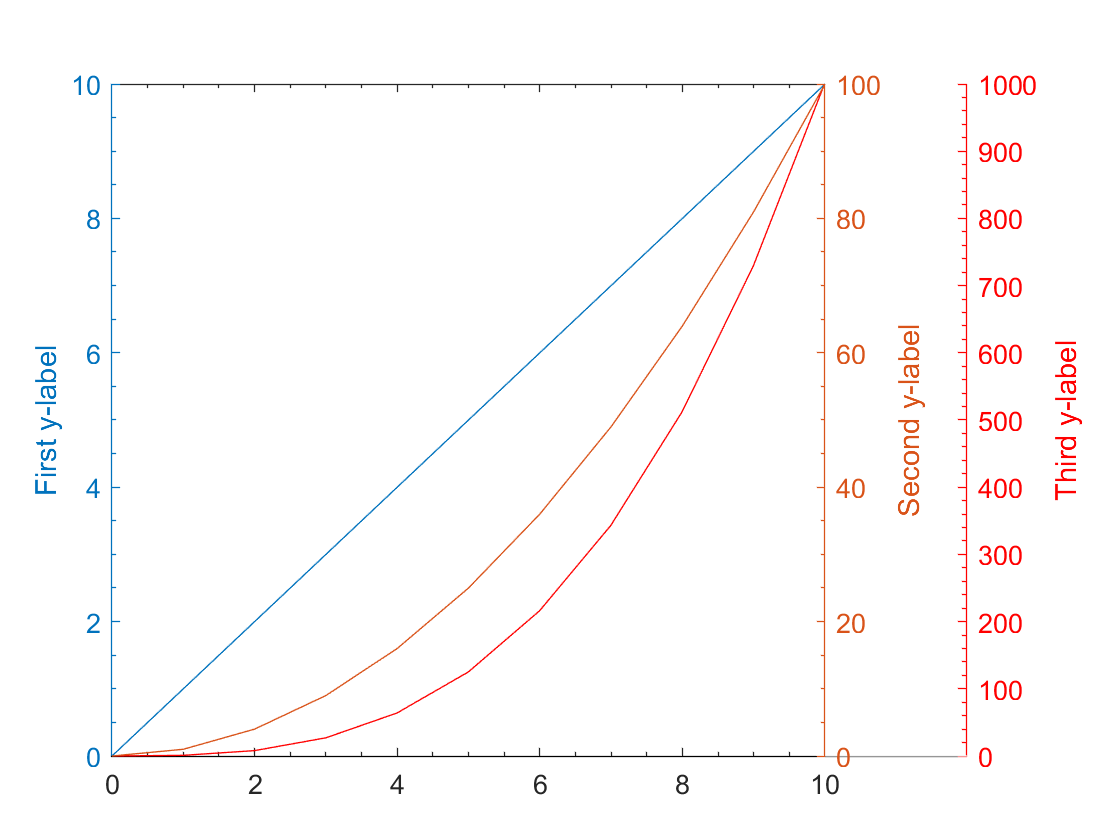


%ylabels[1] = 'A';
%ylabels[2] = 'B';
%ylabels[3] = 'C';
%plotyyy(Otacky,Moment,Otacky,Vykon,Otacky,Vykon2,ylabels)
x=0:10; 
y1=x;  y2=x.^2;   y3=x.^3;
ylabels{1}='First y-label';
ylabels{2}='Second y-label';
ylabels{3}='Third y-label';
[ax,hlines] = plotyyy(x,y1,x,y2,x,y3,ylabels);

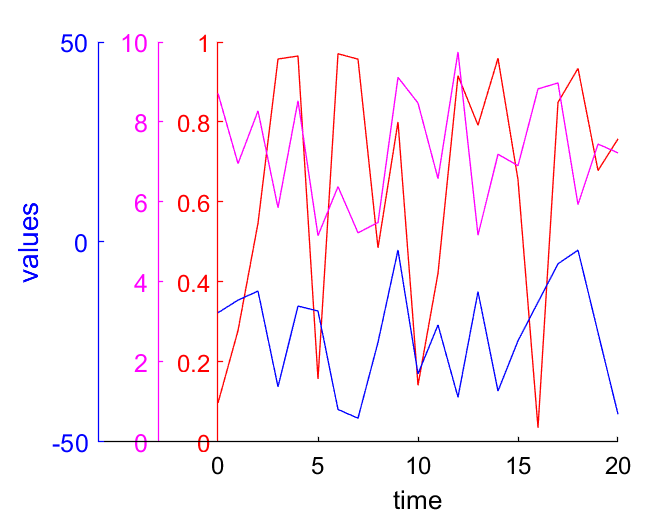




%# Some sample data:
x = 0:20;
N = numel(x);
y1 = rand(1,N);
y2 = 5.*rand(1,N)+5;
y3 = 50.*rand(1,N)-50;

%# Some initial computations:
axesPosition = [110 40 200 200];  %# Axes position, in pixels
yWidth = 30;                      %# y axes spacing, in pixels
xLimit = [min(x) max(x)];         %# Range of x values
xOffset = -yWidth*diff(xLimit)/axesPosition(3);

%# Create the figure and axes:
figure('Units','pixels','Position',[200 200 330 260]);
h1 = axes('Units','pixels','Position',axesPosition,...
          'Color','w','XColor','k','YColor','r',...
          'XLim',xLimit,'YLim',[0 1],'NextPlot','add');
h2 = axes('Units','pixels','Position',axesPosition+yWidth.*[-1 0 1 0],...
          'Color','none','XColor','k','YColor','m',...
          'XLim',xLimit+[xOffset 0],'YLim',[0 10],...
          'XTick',[],'XTickLabel',[],'NextPlot','add');
h3 = axes('Units','pixels','Position',axesPosition+yWidth.*[-2 0 2 0],...
          'Color','none','XColor','k','YColor','b',...
          'XLim',xLimit+[2*xOffset 0],'YLim',[-50 50],...
          'XTick',[],'XTickLabel',[],'NextPlot','add');
xlabel(h1,'time');
ylabel(h3,'values');

%# Plot the data:
plot(h1,x,y1,'r');
plot(h2,x,y2,'m');
plot(h3,x,y3,'b');